from the selected good bouts, decode the prey location in the visual field in a time-varying way.

csessionID = '200108';cfishID = '';
numT = 21;


load(fullfile(getpath('behavior',csessionID,cfishID),'tail_swing'),'good_bout_idx');
load(fullfile(getpath('behavior',csessionID,cfishID),'align_with_fluo'),'align_with_fluo_low');
load(fullfile(getpath('behavior',csessionID,cfishID),'low_video_analysis_result'),'param_head_angle_all','param_head_dist_all');
load(fullfile(getpath('neural activity',csessionID,cfishID),'spikes_new'),'spikes_OASIS');
spikes_OASIS(:,1651:1779) = [];
Spike_X_EstTrace = smoothdata(spikes_OASIS,2,"gaussian",5);
%0108 good bout idx was already aligned to fluo data because its high and
%low fluo is very different from each other
param_head_angle_all = param_head_angle_all(align_with_fluo_low==1);
param_head_angle = mean(reshape(param_head_angle_all(reshape((good_bout_idx(:,1)-[1:20])',[],1)),20,[]),1);
mask = 1:5:nnz(align_with_fluo_low);
[~,hunting_idx_start] = min(abs(row2col(good_bout_idx(:,1),1) - col2row(mask)),[],2);
[~,hunting_idx_end] = min(abs(row2col(good_bout_idx(:,2),1) - col2row(mask)),[],2);
% fluo_idx = randperm(size(Spike_X_EstTrace,2)-numT,nnz(lia));
leftIdx = param_head_angle>0;
rightIdx = param_head_angle<0;
[numRegion,numWholeTime] = size(Spike_X_EstTrace);
numTrial = max(nnz(leftIdx),nnz(rightIdx));
if nnz(leftIdx)>=nnz(rightIdx)
    moreIdx = leftIdx;
    lessIdx = rightIdx;
    disp('left right');
    direction = {'left','right'};
else
    moreIdx = rightIdx;
    lessIdx = leftIdx;
    disp('right left');
    direction = {'right','left'};
end

spk = zeros(length(hunting_idx_start),size(Spike_X_EstTrace,1),numT);%bouts x region x t
for i = 1:length(hunting_idx_start)
    spk(i,:,:) = Spike_X_EstTrace(:,hunting_idx_start(i)+(-floor(numT/2):floor(numT/2)));%region x 5
end
m_spk_left = squeeze(mean(spk(param_head_angle>0,:,:),1));
m_spk_right = squeeze(mean(spk(param_head_angle<0,:,:),1));
%map them on MIP
generate_MIP(m_spk_left+0.01*max(m_spk_left(:)),csessionID,cfishID,'_meanFr_left');
generate_MIP(m_spk_right+0.01*max(m_spk_right(:)),csessionID,cfishID,'_meanFr_right');

missing_data = mean(spk(lessIdx,:,:));%1 x region x time
missing_data = repmat(missing_data,nnz(moreIdx)-nnz(lessIdx),1,1);
spk_balanced = cat(1,spk(moreIdx,:,:),spk(lessIdx,:,:),missing_data);%
spk_balanced = permute(reshape(spk_balanced,nnz(moreIdx),2,numRegion,numT),[3,2,4,1]);%region x direction x time x trial
% [W,V,whichMarg] = drtoolbox.techniques.dpca(mean(spk_balanced,4),5,'combinedParams',{{1},{2},{1,2}});
spk_balanced_ave = mean(spk_balanced,4);%neuron x direction x time
X = spk_balanced_ave(:,:);
X = X - mean(X,2);
[W,explVar,V] = svd(X,'econ');
explVar = diag(explVar)/sum(diag(explVar));
W = W(:,1:numT*2);

% drtoolbox.techniques.dpca_plot(permute(spk_balanced,[1 4 2 3]), W, W, @drtoolbox.techniques.dpca_plot_default);
figure,
plot(explVar/sum(explVar),'-*');axis tight;xlabel('comp');ylabel('explained variance');
figure,
plot(cumsum(explVar/sum(explVar)),'-*');axis tight;xlabel('comp');ylabel('cumulative explained variance');
stdx = permute(std(pagemtimes(W',spk_balanced),[],4)./sqrt([nnz(moreIdx),nnz(lessIdx)]),[3 2 1]);%
multchnPlot(permute(pagemtimes(W',spk_balanced_ave),[3 2 1]),0.1*(-floor(numT/2):floor(numT/2)),[0],'boundwidth',stdx,...
    'plotstyle','boundplot','chnname',arrayfun(@(i) ['comp ' num2str(i)],1:numT*2,'un',0));
sgtitle('signal projection on each component');
xlabel('t/s');ylabel('firing rate');
legend(direction);

generate_MIP(abs(W(:,2)),csessionID,cfishID,'_2ndPC_average_hunting');

%investigate the raw trace of region #356 which contains most 2nd PC time
%series
% load('tail_swing','bout_idx');
[~,bout_idx_aligned_start] = min(abs(row2col(bout_idx(:,1),1) - mask),[],2);
[~,bout_idx_aligned_end] = min(abs(row2col(bout_idx(:,2),1) - mask),[],2);
spk_focus = Spike_X_EstTrace(356,:);
bout_idx_aligned_wholecourse = arrayfun(@(i) (bout_idx_aligned_start(i):bout_idx_aligned_end(i))',1:length(bout_idx),'un',0);
bout_idx_aligned_wholecourse = cat(1,bout_idx_aligned_wholecourse{:});
nonbout_idx = setdiff(1:numWholeTime,bout_idx_aligned_wholecourse);
figure,
group = zeros(numWholeTime,1);group(bout_idx_aligned_wholecourse) = 1;group(nonbout_idx)=2;
subplot(2,1,1)
p = ranksum(spk_focus(bout_idx_aligned_wholecourse),spk_focus(nonbout_idx));
boxplot(spk_focus,group);
sigstar([1 2],p);
set(gca,'XTickLabel',{'bout','nonbout'});
title(['Comparison of neural activity between bout and no bouts: p=' num2str(p)]);
%control
spk_focus_ctrl = spk_focus(randperm(length(spk_focus)));
%and rerun the code above
subplot(2,1,2),
p = ranksum(spk_focus_ctrl(bout_idx_aligned_wholecourse),spk_focus_ctrl(nonbout_idx));
boxplot(spk_focus_ctrl,group);
sigstar([1 2],p);
set(gca,'XTickLabel',{'bout','nonbout'});
title(['control: p=' num2str(p)]);
%hunting bouts and nonhunting bouts
hunting_idx_wholecourse = arrayfun(@(i) (hunting_idx_start(i):hunting_idx_end(i))',1:length(hunting_idx_start),'un',0);
hunting_idx_wholecourse = cat(1,hunting_idx_wholecourse{:});
p = ranksum(spk_focus(hunting_idx_wholecourse),spk_focus(setdiff(bout_idx_aligned_wholecourse,hunting_idx_wholecourse)));
figure,
subplot(2,1,1),
group = 2*ones(length(bout_idx_aligned_wholecourse),1);
group(ismember(bout_idx_aligned_wholecourse,hunting_idx_wholecourse)) = 1;
boxplot(spk_focus(bout_idx_aligned_wholecourse),group);
hold on;
sigstar([1 2],p);
set(gca,'XTickLabel',{'hunting bouts','nonhunting bouts'});
subplot(2,1,2),
group = 2*ones(length(bout_idx_aligned_wholecourse),1);
group(ismember(bout_idx_aligned_wholecourse,hunting_idx_wholecourse)) = 1;
boxplot(spk_focus(bout_idx_aligned_wholecourse),group(randperm(length(bout_idx_aligned_wholecourse))));
hold on;
idxtmp=randperm(length(bout_idx_aligned_wholecourse),length(hunting_idx_wholecourse));
p = ranksum(spk_focus(bout_idx_aligned_wholecourse(idxtmp)),spk_focus(bout_idx_aligned_wholecourse(setdiff(1:length(bout_idx_aligned_wholecourse),idxtmp))));
sigstar([1 2],p);
set(gca,'XTickLabel',{'hunting bouts','nonhunting bouts'});
title('control');
sgtitle('comparison between hunting and nonhuting bouts');
set(gca,'XTickLabel',{'hunting','nonhunting'});
%compare nonhunting bouts and nonbouts
figure,
x1 = spk_focus(setdiff(1:numWholeTime,bout_idx_aligned_wholecourse))';
x2 = spk_focus(setdiff(bout_idx_aligned_wholecourse,hunting_idx_wholecourse))';
x = cat(1,x2,x1);
group = [ones(length(x2),1);2*ones(length(x1),1)];
p = ranksum(x1,x2);
subplot(2,1,1),
boxplot(x,group);hold on;
sigstar([1 2],p);
set(gca,'XTickLabel',{'nonhunting bouts','nonbouts'});
subplot(2,1,2),
randidx = randperm(length(x));
p = ranksum(x(randidx(1:length(x1))),x(randidx((length(x1)+1):end)));
boxplot(x,group(randidx));hold on;
sigstar([1 2],p);
sgtitle('comparison between nonhunting bouts and nonbouts');
%compare left and right bouts
figure,
x1 = arrayfun(@(i) (hunting_idx_start(i):hunting_idx_end(i))',find(param_head_angle>0),'un',0);
x1 = spk_focus(cat(1,x1{:}))';%left
x2 = arrayfun(@(i) (hunting_idx_start(i):hunting_idx_end(i))',find(param_head_angle<0),'un',0);
x2 = spk_focus(cat(1,x2{:}))';%right
x = cat(1,x2,x1);
group = [ones(length(x2),1);2*ones(length(x1),1)];
p = ranksum(x1,x2);
subplot(2,1,1),
boxplot(x,group);hold on;
sigstar([1 2],p);
set(gca,'XTickLabel',{'right','left'});
subplot(2,1,2),
randidx = randperm(length(x));
p = ranksum(x(randidx(1:length(x1))),x(randidx((length(x1)+1):end)));
boxplot(x,group(randidx));hold on;
sigstar([1 2],p);
sgtitle('comparison between left and right hunting bouts');
%compare left and right vision
x1 = spk_focus(hunting_idx_wholecourse(param_head_angle_fluo(hunting_idx_wholecourse)>0))';
x2 = spk_focus(hunting_idx_wholecourse(param_head_angle_fluo(hunting_idx_wholecourse)<0))';
px = ranksum(x1,x2);
simul_bout_idx_wholecourse = setdiff(bout_idx_aligned_wholecourse,hunting_idx_wholecourse);
y1 = spk_focus(simul_bout_idx_wholecourse(param_head_angle_fluo(simul_bout_idx_wholecourse)>0))';
y2 = spk_focus(simul_bout_idx_wholecourse(param_head_angle_fluo(simul_bout_idx_wholecourse)<0))';
y = cat(1,y1,y2);
py = ranksum(y1,y2);
rest_idx_wholecourse = setdiff(1:numWholeTime,bout_idx_aligned_wholecourse);
z1 = spk_focus(rest_idx_wholecourse(param_head_angle_fluo(rest_idx_wholecourse)>0))';
z2 = spk_focus(rest_idx_wholecourse(param_head_angle_fluo(rest_idx_wholecourse)<0))';
pz = ranksum(z1,z2);
data = {x1,x2;y1,y2;z1,z2};
h = boxplot2(data);
set(gca,'XTick',[1 2 3],'XTickLabel',{'hunting','simultaneous','resting'});
sigstar([h.lwhis(1,1).XData(1) h.lwhis(2,1).XData(1)],px);
sigstar([h.lwhis(1,2).XData(1) h.lwhis(2,2).XData(1)],py);
sigstar([h.lwhis(1,3).XData(1) h.lwhis(2,3).XData(1)],pz);
sigstar([h.lwhis(1,1).XData(1) h.lwhis(1,2).XData(1)],ranksum(x1,y1));
sigstar([h.lwhis(1,2).XData(1) h.lwhis(1,3).XData(1)],ranksum(z1,y1));
sigstar([h.lwhis(2,1).XData(1) h.lwhis(2,2).XData(1)],ranksum(x2,y2));
sigstar([h.lwhis(2,2).XData(1) h.lwhis(2,3).XData(1)],ranksum(z2,y2));
title('Left Right visual encoding');

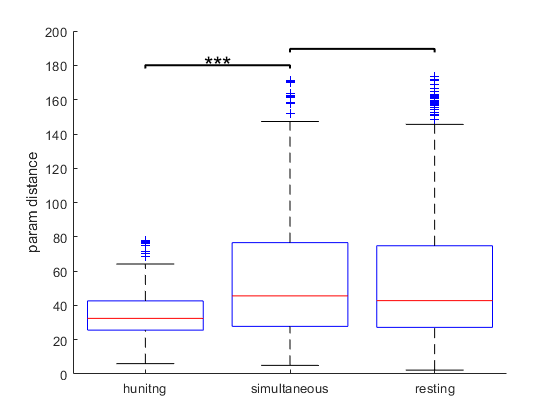

%if the left/right difference comes from the distance/angle
idx_no_param = find(param_head_dist_fluo>300);
hunting_idx_wholecourse(ismember(hunting_idx_wholecourse,idx_no_param)) = [];
simul_bout_idx_wholecourse(ismember(simul_bout_idx_wholecourse,idx_no_param)) = [];
rest_idx_wholecourse(ismember(rest_idx_wholecourse,idx_no_param)) = [];
dx = param_head_dist_fluo(hunting_idx_wholecourse);
dy = param_head_dist_fluo(simul_bout_idx_wholecourse);
dz = param_head_dist_fluo(rest_idx_wholecourse);
data = {dx,dy,dz};
figure,
boxplot2(data');
pxy = ranksum(dx,dy);pyz = ranksum(dy,dz);
hold on;
sigstar([1 2],pxy);sigstar([2 3],pyz);
ylabel('param distance');
set(gca,'XTick',[1 2 3],'XTickLabel',{'hunitng','simultaneous','resting'});

%behavior state x left/right
behav_var = param_head_dist_fluo;
idx_behav7direct = cell(3,2);
idx_behav7direct{1,1} = hunting_idx_wholecourse(param_head_angle_fluo(hunting_idx_wholecourse)>0);
idx_behav7direct{1,2} = hunting_idx_wholecourse(param_head_angle_fluo(hunting_idx_wholecourse)<0);
idx_behav7direct{2,1} = simul_bout_idx_wholecourse(param_head_angle_fluo(simul_bout_idx_wholecourse)>0);
idx_behav7direct{2,2} = simul_bout_idx_wholecourse(param_head_angle_fluo(simul_bout_idx_wholecourse)<0);
idx_behav7direct{3,1} = rest_idx_wholecourse(param_head_angle_fluo(rest_idx_wholecourse)>0);
idx_behav7direct{3,2} = rest_idx_wholecourse(param_head_angle_fluo(rest_idx_wholecourse)<0);
spk_behav7direct = cellfun(@(x) spk_focus(x)',idx_behav7direct,'un',0);
dist_behav7direct = cellfun(@(x) behav_var(x),idx_behav7direct,'un',0);
xlim = [min(cellfun(@min,dist_behav7direct),[],'all') max(cellfun(@max,dist_behav7direct),[],'all')];
ylim = [min(cellfun(@min,spk_behav7direct),[],'all') max(cellfun(@max,spk_behav7direct),[],'all')]

ylim =          0    0.5147


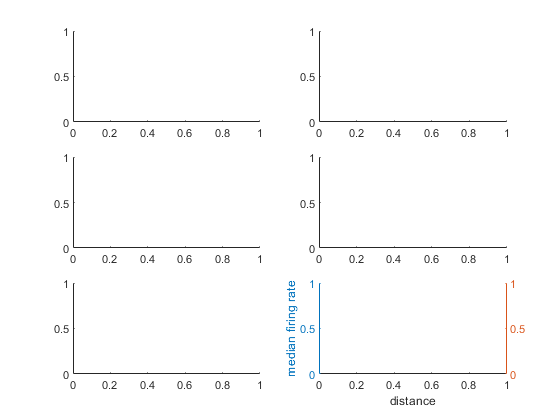

figure,
coeff = zeros(3,2,2);GOF = zeros(3,2);
Edge = cell(3,2);M_SPK = cell(3,2);Weight = cell(3,2);
for i=1:3
    for j=1:2
        subplot(3,2,(i-1)*2+j),
%         scatter(dist_behav7direct{i,j},spk_behav7direct{i,j},10,'filled');hold on;
        [Y,edges] = discretize(dist_behav7direct{i,j},0:1:max(dist_behav7direct{i,j}));
        m_spk = arrayfun(@(k) quantile(spk_behav7direct{i,j}(Y==k),0.75),1:(length(edges)-1));
%         m_spk(isnan(m_spk)) = 0;        
        [N,xedge] = histcounts(dist_behav7direct{i,j},edges);
        m_spk(N==0) = [];
        edges(N==0) = [];
        xedge(N==0) = [];
        N(N==0) = [];
        Edge{i,j} = edges(1:end-1);
        M_SPK{i,j} = m_spk;
        Weight{i,j} = N;
%         scatter(edges(1:end-1),m_spk,N);
        [f,gof] = fit(edges(1:end-1)',m_spk','poly1','weights',N/sum(N));
        coeff(i,j,:) = [f.p1 f.p2];% f.p3];
        GOF(i,j) = gof.rsquare;
%         yest = f.p1*edges(1:end-1)+f.p2;
%         hold on;plot(edges(1:end-1),yest);
%         text(edges(1),yest(1),num2str(gof.rsquare));
%         p_obs = f.p1;
%         p_shuffle = zeros(1000,1);
        %shuffle test
%         for iperm = 1:1000
%             randidx = randperm(length(m_spk));
%             f = fit(edges(1:end-1)',m_spk(randidx)','poly1','weights',N/sum(N));
%             p_shuffle(iperm) = f.p1;
%         end
%         h = ttest(p_shuffle)
%         title(['normal? :' num2str(h) 'p value:' num2str(mean(p_shuffle<p_obs),3)]);
%         [f,gof] = fit(edges(1:end-1)',m_spk','exp1','weights',N/sum(N));
%         yest =f.a*exp(f.b*edges(1:end-1));
%         hold on;plot(edges(1:end-1),yest);
%         text(edges(end-1),yest(end-1),num2str(gof.rsquare));
%         yyaxis right;
%         plot(xedge(1:end-1),N);
%         axis tight;
%         [N,xedge,yedge] = histcounts2(dist_behav7direct{i,j},spk_behav7direct{i,j},'BinWidth',[2 0.01],'Normalization','probability','XBinLimits',xlim,'YbinLimits',ylim);
%         N = N./sum(N,2);
%         imagesc(N);
%         set(gca,'XTick',1:length(yedge),'XTickLabel',yedge,'YTick',1:length(xedge),'YTickLabel',xedge);
    end
end
xlabel('distance');ylabel('probability');yyaxis left;ylabel('median firing rate');

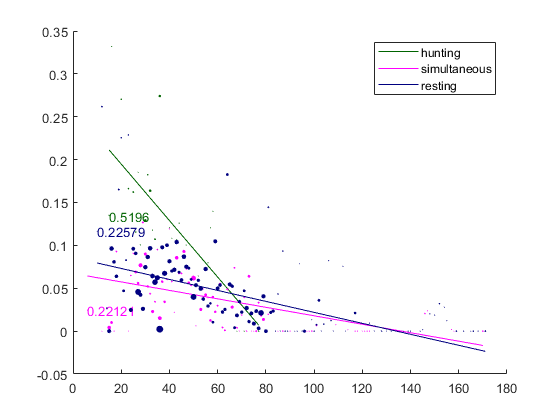

%demix the distance and behavior state condition
figure,
color = rgb({'darkgreen','magenta','navy'});
hold on,
lateral = 2;
for i=1:3
   scatter(Edge{i,lateral},M_SPK{i,lateral},Weight{i,lateral},color(i,:),'filled');
%    h(i) = plot(Edge{i,lateral},coeff(i,lateral,1)*(Edge{i,lateral}.^2)+coeff(i,lateral,2)*Edge{i,lateral}+coeff(i,lateral,3),'Color',color(i,:));
    h(i) = plot(Edge{i,lateral},coeff(i,lateral,1)*Edge{i,lateral}+coeff(i,lateral,2),'Color',color(i,:));
    text(Edge{i,lateral}(1),M_SPK{i,lateral}(1),num2str(GOF(i,lateral)),'Color',color(i,:));
end
legend(h,{'hunting','simultaneous','resting'});

 %select the timeponits of simultaneous state which has the same distance
 %with hunting, and compare their firing rates
 dlim = [min(dx) max(dx)];
 idxtmp = find(dy<dlim(2)&dy>dlim(1));
 randidx = randperm(length(idxtmp),length(dx));
 dy_sel = dy(idxtmp(randidx));


%decode left/right using time points at different behavior states


plot the evolution trajectory along time

proj_X = W(:,[2 4])'*Spike_X_EstTrace;%2 x time
basecolor = rgb({'magenta','grassgreen'});
color = basecolor(moreIdx+2*lessIdx,:);
% plot_evolution_trajectory(proj_X','marker',reshape((fluo_idx+[-5:5])',[],1),...
%     'color',color(reshape(repmat([1:length(fluo_idx)],11,1),[],1),:));
plot_evolution_trajectory(proj_X','marker',[hunting_idx_start hunting_idx_end],'color',color);
xlabel('PC2');ylabel('PC4');

%plot all bouts' projection
load('tail_swing.mat', 'bout_idx');
[~,hunting_idx_start] = min(abs(row2col(bout_idx(:,1),1) - col2row(mask)),[],2);
[~,hunting_idx_end] = min(abs(row2col(bout_idx(:,2),1) - col2row(mask)),[],2);
moreIdx = param_head_angle_fluo(hunting_idx_start)>0;
lessIdx = param_head_angle_fluo(hunting_idx_start)<0;
basecolor = rgb({'magenta','greenyellow'});
color = basecolor(moreIdx+2*lessIdx,:);
plot_evolution_trajectory(proj_X','marker',[hunting_idx_start hunting_idx_end],'color',color);

pcoi = [1 2 3 4 5];
arrayfun(@(i) generate_MIP(W(:,i),csessionID,cfishID,['_' num2str(i) 'ndPC_random']),pcoi,'un',0);

spk = permute(spk,[2 1 3]);%area x trial x time
% dpca(spk(:,param_head_angle>0,:),);%

X = cat(3,squeeze(spk_balanced(:,1,:,:)),squeeze(spk_balanced(:,2,:,1:nnz(lessIdx))));%region x time x trial
proj_X = pagemtimes(W(:,1:3)',X);%3 x time x trial
label = [zeros(nnz(moreIdx),1);ones(nnz(lessIdx),1)];
X = reshape(proj_X,3*numT,length(label))';
% X = repmat(X,2,1);
% label = repmat(label,2,1);
numFold = 3;
c = cvpartition(label,'KFold',numFold);
accu = zeros(numFold,1);
Coeff = zeros(1+size(X,2),numFold);
for i=1:numFold
    idxTest = c.test(i);
    idxTrain = ~idxTest;
    [B,fitInfo] = lassoglm(X(idxTrain,:),label(idxTrain),'binomial','CV',5);
    idxMinDev = fitInfo.IndexMinDeviance;
    coeff = [fitInfo.Intercept(idxMinDev);B(:,idxMinDev)];
    Coeff(:,i) = coeff;
    labelhat = glmval(coeff,X(idxTest,:),'logit',fitInfo);
    accu(i) = mean((labelhat>=0.5)==label(idxTest));
end

Next, we want to find the visual information encoded in neural activity.

param_head_angle_fluo = accumarray(reshape(repmat(1:length(param_head_angle_all)/5,5,1),[],1),param_head_angle_all);
leftIdx = param_head_angle_fluo>0;
rightIdx = param_head_angle_fluo<0;
if nnz(leftIdx)>=nnz(rightIdx)
    moreIdx = leftIdx;lessIdx = rightIdx;
    disp('left right');
    direction = {'left','right'};
    
else
    moreIdx = rightIdx;lessIdx = leftIdx;
    disp('right left');
    direction = {'right','left'};
end
numTrial = nnz(moreIdx);
Spike_X_EstTrace(:,moreIdx);
missingData = repmat(mean(Spike_X_EstTrace(:,lessIdx),2),1,nnz(moreIdx)-nnz(lessIdx));
X = cat(3,Spike_X_EstTrace(:,moreIdx),[Spike_X_EstTrace(:,lessIdx),missingData]);
%region x trial x 2(more&less)
X = permute(X,[1 3 2]);%region x 2 x trial
X_ave = mean(X,3);

%first use averaged data for decomposition
[W,sigma,V] = svd(X_ave,'econ');
sigma = diag(sigma);
proj_X = pagemtimes(W',X);%2 x 2 x trial
meanx = mean(proj_X,3);%2 x 2
stdx = std(proj_X,[],3)./sqrt([nnz(moreIdx) nnz(lessIdx)]);%2 x 2, PC x class
figure,
h = barwitherr(stdx,meanx);
p = arrayfun(@(i) ranksum(squeeze(proj_X(i,1,:)),squeeze(proj_X(i,2,1:nnz(lessIdx)))),1:2);
set(gca,'XTickLabel',{'PC1','PC2'});
ylabel('projected amplitude of all timepoints')
legend(direction);
figure,
bar(sigma/sum(sigma));
ylabel('explained variance');

generate_MIP(W(:,1),csessionID,cfishID,'_visual_1stPC');
generate_MIP(W(:,2),csessionID,cfishID,'_visual_2ndPC');

[W,sigma,V] = svd(X(:,:),'econ');
sigma = diag(sigma);
W = W(:,1:15);
proj_X = pagemtimes(W',X);%pc x 2 x trial
meanx = mean(proj_X,3);%pc x 2
stdx = std(proj_X,[],3)./sqrt([nnz(moreIdx) nnz(lessIdx)]);%2 x 2, PC x class
figure,
h = barwitherr(stdx,meanx);
p = arrayfun(@(i) ranksum(squeeze(proj_X(i,1,:)),squeeze(proj_X(i,2,1:nnz(lessIdx)))),1:2);
set(gca,'XTickLabel',{'PC1','PC2'});
ylabel('projected amplitude of all timepoints')
legend(direction);
figure,
plot(sigma/sum(sigma));
ylabel('explained variance');

bout_idx_aligned_wholecourse = [2 3 4 6 7 10];
arrayfun(@(i) generate_MIP(W(:,i),csessionID,cfishID,['_visual_' num2str(i) 'thPC']),bout_idx_aligned_wholecourse);

Next we may try to regress the prey location and tail curvature using extracted PC 